f=@(x) 0.2+25.*x-200.*x.^2+675.*x.^3-900.*x.^4+400.*x.^5;
xx = linspace(0,0.8)

xx =          0    0.0081    0.0162    0.0242    0.0323    0.0404    0.0485    0.0566    0.0646    0.0727    0.0808    0.0889    0.0970    0.1051    0.1131    0.1212    0.1293    0.1374    0.1455    0.1535    0.1616    0.1697    0.1778    0.1859    0.1939    0.2020    0.2101    0.2182    0.2263    0.2343    0.2424    0.2505    0.2586    0.2667    0.2747    0.2828    0.2909    0.2990    0.3071    0.3152    0.3232    0.3313    0.3394    0.3475    0.3556    0.3636    0.3717    0.3798    0.3879    0.3960


yy = f(xx)

yy =     0.2000    0.3893    0.5546    0.6978    0.8209    0.9258    1.0140    1.0874    1.1474    1.1956    1.2334    1.2621    1.2829    1.2972    1.3059    1.3101    1.3108    1.3090    1.3054    1.3008    1.2960    1.2915    1.2881    1.2862    1.2863    1.2889    1.2943    1.3029    1.3148    1.3305    1.3500    1.3735    1.4010    1.4327    1.4686    1.5086    1.5527    1.6007    1.6527    1.7083    1.7675    1.8300    1.8956    1.9640    2.0349    2.1081    2.1832    2.2598    2.3377    2.4164


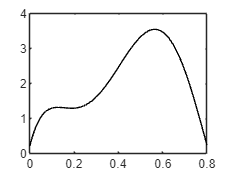

plot(xx,yy,'k-')

a = 0

a = 0

b = 0.8

b = 0.8000

p =[400 -900 675 -200 25 0.2]

p =   400.0000 -900.0000  675.0000 -200.0000   25.0000    0.2000


q = polyint(p)

q =    66.6667 -180.0000  168.7500  -66.6667   12.5000    0.2000         0


Itrue = diff(polyval(q,[a,b]))

Itrue = 1.6405

a = 1.6405

ns = 1

ns = 1

x = linspace(a,b,ns+1)

x =     1.6405    0.8000


y = f(x)

y =   717.4011    0.2320


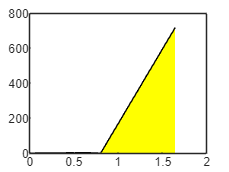


figure
area(x,y,'FaceColor','y','EdgeColor','black','LineStyle','-')
hold on
plot(xx,yy,'k-')

I_trap_1 = trap(f,a,b,1)

trap is not found in the current folder or on the MATLAB path, but exists in:
    C:\Users\gifly\Documents\GitHub\MATLAB\Lec14 class materials-20240426\practice questions
    C:\Users\gifly\Documents\GitHub\MATLAB\Lec13 class materials-20240419\practice questions

Change the MATLAB current folder or add its folder to the MATLAB path.

I_trap_4 = trap(f,a,b,4)

ns = 1
x = linspace(a,b,2*ns+1)
y = f(x)

p2 = polyfit(x,y,2)
yy2 = polyval(p2,xx)
yy3 = polyval(p2,x)
figure
area(xx,yy2,'FaceColor','y','EdgeColor','black','LineStyle','-')
hold on
plot(x,y,'m*')
plot(xx,yy,'k-')
